url = 'http://ssd.mathworks.com/supportfiles/audio/commonvoice.zip';
downloadFolder = tempdir;
datafolder = fullfile(downloadFolder,'commonvoice');

if ~exist(datafolder,'dir')
    disp('Downloading data set (956 MB) ...')
    unzip(url,downloadFolder)
end

% datafolder = PathToDatabase;

Dead code

% ads0 = audioDatastore(fullfile(datafolder,"clips"));
% metadata = readtable(fullfile(datafolder,"train.tsv"),"FileType","text");
% head(metadata)
% csvFiles = metadata.path;
% adsFiles = ads0.Files;
% [~,adsFiles,ext] = cellfun(@(x)fileparts(x),adsFiles,'UniformOutput',false);
% [~,indA] = intersect(strcat(adsFiles,ext),csvFiles);
% ads = subset(ads0,indA);
% numFilesInSubset = 1000;
% a

adsTrain = audioDatastore(fullfile(dataFolder,'train'),'IncludeSubfolders',true);

reduceDataset = true;
if reduceDataset
    adsTrain = shuffle(adsTrain);
    adsTrain = subset(adsTrain,1:1000);
end

ads = adsTrain

ads =   audioDatastore - 属性:

                       Files: {
                              ' ...\Local\Temp\commonvoice\train\clips\common_voice_en_19836329.wav';
                              ' ...\Local\Temp\commonvoice\train\clips\common_voice_en_18680942.wav';
                              ' ...\Local\Temp\commonvoice\train\clips\common_voice_en_18524959.wav'
                               ... and 997 more
                              }
                     Folders: {
                              'C:\Users\PotatoMonster\AppData\Local\Temp\commonvoice\train'
                              }
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
                      Labels: {}
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


Use `read` to get the contents of the first file in the datastore.

[audio,adsInfo] = read(adsTrain);
% [audio,adsInfo] = read(ads);

Listen to the speech signal.

sound(audio,adsInfo.SampleRate)

Plot the speech signal.

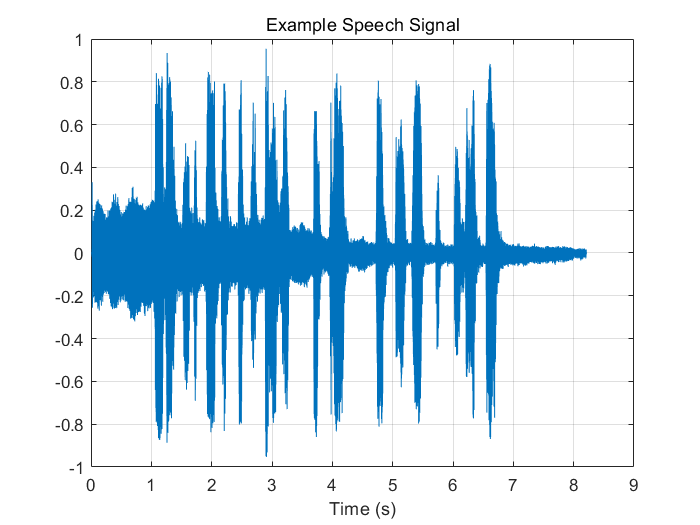

figure
t = (1/adsInfo.SampleRate) * (0:numel(audio)-1);
plot(t,audio)
title("Example Speech Signal")
xlabel("Time (s)")
grid on

windowLength = 256;
win = hamming(windowLength,"periodic");
overlap = round(0.75 * windowLength);
ffTLength = windowLength;
inputFs = 48e3;
fs = 8e3;
numFeatures = ffTLength/2 + 1;
numSegments = 8;

src = dsp.SampleRateConverter("InputSampleRate",inputFs, ...
                              "OutputSampleRate",fs, ...
                              "Bandwidth",7920);

audio = read(ads);

decimationFactor = inputFs/fs;
L = floor(numel(audio)/decimationFactor);
audio = audio(1:decimationFactor*L);

audio = src(audio);
reset(src)

randind = randi(numel(noise) - numel(audio),[1 1]);
noiseSegment = noise(randind : randind + numel(audio) - 1);

noisePower = sum(noiseSegment.^2);
cleanPower = sum(audio.^2);
noiseSegment = noiseSegment .* sqrt(cleanPower/noisePower);
noisyAudio = audio + noiseSegment;

cleanSTFT = stft(audio,'Window',win,'OverlapLength',overlap,'FFTLength',ffTLength);
cleanSTFT = abs(cleanSTFT(numFeatures-1:end,:));
noisySTFT = stft(noisyAudio,'Window',win,'OverlapLength',overlap,'FFTLength',ffTLength);
noisySTFT = abs(noisySTFT(numFeatures-1:end,:));

noisySTFT = [noisySTFT(:,1:numSegments - 1), noisySTFT];
stftSegments = zeros(numFeatures, numSegments , size(noisySTFT,2) - numSegments + 1);
for index = 1:size(noisySTFT,2) - numSegments + 1
    stftSegments(:,:,index) = (noisySTFT(:,index:index + numSegments - 1)); 
end

targets = cleanSTFT;
size(targets)

ans =    129   577


predictors = stftSegments;
size(predictors)

ans =    129     8   577


reset(ads)
T = tall(ads)

T =

  M×1 tall cell 数组

    {196464×1 double}
    {222960×1 double}
    {182640×1 double}
    {300144×1 double}
    {234480×1 double}
    {324336×1 double}
    {340464×1 double}
    {265584×1 double}
        :        :
        :        :



[targets,predictors] = cellfun(@(x)HelperGenerateSpeechDenoisingFeatures(x,noise,src),T,"UniformOutput",false);

[targets,predictors] = gather(targets,predictors);

正在使用 本地 MATLAB 会话 计算 tall 表达式:
- 第 1 次遍历(共 1 次): 已完成 8%
计算已完成 7%


predictors = cat(3,predictors{:});
noisyMean = mean(predictors(:));
noisyStd = std(predictors(:));
predictors(:) = (predictors(:) - noisyMean)/noisyStd;

targets = cat(2,targets{:});
cleanMean = mean(targets(:));
cleanStd = std(targets(:));
targets(:) = (targets(:) - cleanMean)/cleanStd;

predictors = reshape(predictors,size(predictors,1),size(predictors,2),1,size(predictors,3));
targets = reshape(targets,1,1,size(targets,1),size(targets,2));

inds = randperm(size(predictors,4));
L = round(0.99 * size(predictors,4));

trainPredictors = predictors(:,:,:,inds(1:L));
trainTargets = targets(:,:,:,inds(1:L));

validatePredictors = predictors(:,:,:,inds(L+1:end));
validateTargets = targets(:,:,:,inds(L+1:end));

layers = [
    imageInputLayer([numFeatures,numSegments])
    fullyConnectedLayer(1024)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(1024)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numFeatures)
    regressionLayer
    ];

miniBatchSize = 128;
options = trainingOptions("adam", ...
    "MaxEpochs",3, ...
    "InitialLearnRate",1e-5,...
    "MiniBatchSize",miniBatchSize, ...
    "Shuffle","every-epoch", ...
    "Plots","training-progress", ...
    "Verbose",false, ...
    "ValidationFrequency",floor(size(trainPredictors,4)/miniBatchSize), ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropFactor",0.9, ...
    "LearnRateDropPeriod",1, ...
    "ValidationData",{validatePredictors,validateTargets});

doTraining = true;
if doTraining
    denoiseNetFullyConnected = trainNetwork(trainPredictors,trainTargets,layers,options);
else
    s = load("denoisenet.mat");
    denoiseNetFullyConnected = s.denoiseNetFullyConnected;
    cleanMean = s.cleanMean;
    cleanStd = s.cleanStd;
    noisyMean = s.noisyMean;
    noisyStd = s.noisyStd;
end

numWeights = 0;
for index = 1:numel(denoiseNetFullyConnected.Layers)
    if isa(denoiseNetFullyConnected.Layers(index),"nnet.cnn.layer.FullyConnectedLayer")
        numWeights = numWeights + numel(denoiseNetFullyConnected.Layers(index).Weights);
    end
end
fprintf("The number of weights is %d.\n",numWeights);

layers = [imageInputLayer([numFeatures,numSegments])
          convolution2dLayer([9 8],18,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer
          
          repmat( ...
          [convolution2dLayer([5 1],30,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer
          convolution2dLayer([9 1],8,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer
          convolution2dLayer([9 1],18,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer],4,1)
          
          convolution2dLayer([5 1],30,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer
          convolution2dLayer([9 1],8,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer
          
          convolution2dLayer([129 1],1,"Stride",[1 100],"Padding","same")
          
          regressionLayer
          ];

The training options are identical to the options for the fully connected network, except that the dimensions of the validation target signals are permuted to be consistent with the dimensions expected by the regression layer.

options = trainingOptions("adam", ...
    "MaxEpochs",3, ...
    "InitialLearnRate",1e-5, ...
    "MiniBatchSize",miniBatchSize, ...
    "Shuffle","every-epoch", ...
    "Plots","training-progress", ...
    "Verbose",false, ...
    "ValidationFrequency",floor(size(trainPredictors,4)/miniBatchSize), ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropFactor",0.9, ...
    "LearnRateDropPeriod",1, ...
    "ValidationData",{validatePredictors,permute(validateTargets,[3 1 2 4])});

doTraining = true;
if doTraining
    denoiseNetFullyConvolutional = trainNetwork(trainPredictors,permute(trainTargets,[3 1 2 4]),layers,options);
else
    s = load("denoisenet.mat");
    denoiseNetFullyConvolutional = s.denoiseNetFullyConvolutional;
    cleanMean = s.cleanMean;
    cleanStd = s.cleanStd;
    noisyMean = s.noisyMean;
    noisyStd = s.noisyStd;
end

numWeights = 0;
for index = 1:numel(denoiseNetFullyConvolutional.Layers)
    if isa(denoiseNetFullyConvolutional.Layers(index),"nnet.cnn.layer.Convolution2DLayer")
        numWeights = numWeights + numel(denoiseNetFullyConvolutional.Layers(index).Weights);
    end
end
fprintf("The number of weights in convolutional layers is %d\n",numWeights);

## Dead Code

% metadata = readtable(fullfile(datafolder,"test.tsv"),"FileType","text");
% csvFiles = metadata.path;
% adsFiles = ads0.Files;
% [~,adsFiles,ext] = cellfun(@(x)fileparts(x),adsFiles,'UniformOutput',false);
% [~,indA] = intersect(strcat(adsFiles,ext),csvFiles);
% ads = subset(ads0,indA);
% ads = subset(ads,1:100);
% ads = shuffle(ads);
% adsTest = audioDatastore(fullfile(dataFolder,'test'),'IncludeSubfolders',true);

input = fullfile('C:\Users\PotatoMonster\Documents\MATLAB\Examples\R2020a\deeplearning_shared\DenoiseSpeechUsingDeepLearningNetworksExample\input\')

input = 'C:\Users\PotatoMonster\Documents\MATLAB\Examples\R2020a\deeplearning_shared\DenoiseSpeechUsingDeepLearningNetworksExample\input\'

adsTest = audioDatastore(input,'IncludeSubfolders',true);

% [cleanAudio,adsInfo] = read(ads);
[cleanAudio,adsInfo] = read(adsTest);

L = floor(numel(cleanAudio)/decimationFactor);
cleanAudio = cleanAudio(1:decimationFactor*L);

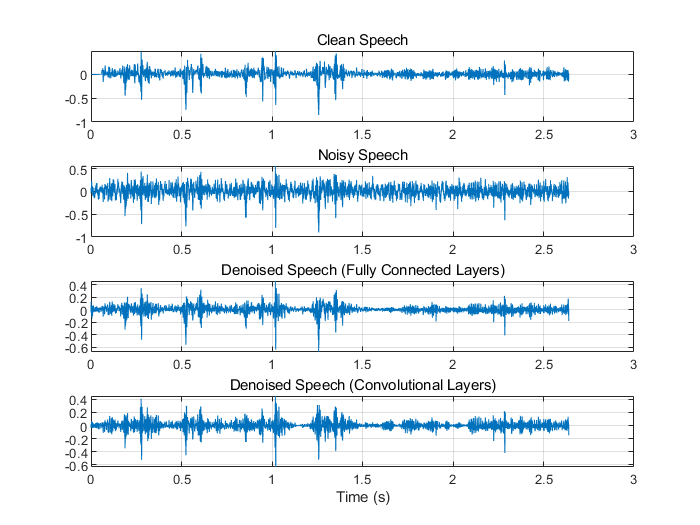

cleanAudio = src(cleanAudio);
reset(src)

noise = audioread("WashingMachine-16-8-mono-200secs.wav");

randind = randi(numel(noise) - numel(cleanAudio), [1 1]);
noiseSegment = noise(randind : randind + numel(cleanAudio) - 1);

noisePower = sum(noiseSegment.^2);
cleanPower = sum(cleanAudio.^2);
noiseSegment = noiseSegment .* sqrt(cleanPower/noisePower);
noisyAudio = cleanAudio + noiseSegment;
% noisyAudio = cleanAudio;

noisySTFT = stft(noisyAudio,'Window',win,'OverlapLength',overlap,'FFTLength',ffTLength);
noisyPhase = angle(noisySTFT(numFeatures-1:end,:));
noisySTFT = abs(noisySTFT(numFeatures-1:end,:));

noisySTFT = [noisySTFT(:,1:numSegments-1) noisySTFT];
predictors = zeros( numFeatures, numSegments , size(noisySTFT,2) - numSegments + 1);
for index = 1:(size(noisySTFT,2) - numSegments + 1)
    predictors(:,:,index) = noisySTFT(:,index:index + numSegments - 1); 
end

predictors(:) = (predictors(:) - noisyMean) / noisyStd;

predictors = reshape(predictors, [numFeatures,numSegments,1,size(predictors,3)]);
STFTFullyConnected = predict(denoiseNetFullyConnected, predictors);
STFTFullyConvolutional = predict(denoiseNetFullyConvolutional, predictors);

STFTFullyConnected(:) = cleanStd * STFTFullyConnected(:) + cleanMean;
STFTFullyConvolutional(:) = cleanStd * STFTFullyConvolutional(:) + cleanMean;

STFTFullyConnected = STFTFullyConnected.' .* exp(1j*noisyPhase);
STFTFullyConnected = [conj(STFTFullyConnected(end-1:-1:2,:)); STFTFullyConnected];
STFTFullyConvolutional = squeeze(STFTFullyConvolutional) .* exp(1j*noisyPhase);
STFTFullyConvolutional = [conj(STFTFullyConvolutional(end-1:-1:2,:)) ; STFTFullyConvolutional];

denoisedAudioFullyConnected = istft(STFTFullyConnected,  ...
                                    'Window',win,'OverlapLength',overlap, ...
                                    'FFTLength',ffTLength,'ConjugateSymmetric',true);
                                
denoisedAudioFullyConvolutional = istft(STFTFullyConvolutional,  ...
                                        'Window',win,'OverlapLength',overlap, ...
                                        'FFTLength',ffTLength,'ConjugateSymmetric',true);

t = (1/fs) * (0:numel(denoisedAudioFullyConnected)-1);

figure

subplot(4,1,1)
plot(t,cleanAudio(1:numel(denoisedAudioFullyConnected)))
title("Clean Speech")
grid on

subplot(4,1,2)
plot(t,noisyAudio(1:numel(denoisedAudioFullyConnected)))
title("Noisy Speech")
grid on

subplot(4,1,3)
plot(t,denoisedAudioFullyConnected)
title("Denoised Speech (Fully Connected Layers)")
grid on

subplot(4,1,4)
plot(t,denoisedAudioFullyConvolutional)
title("Denoised Speech (Convolutional Layers)")
grid on
xlabel("Time (s)")

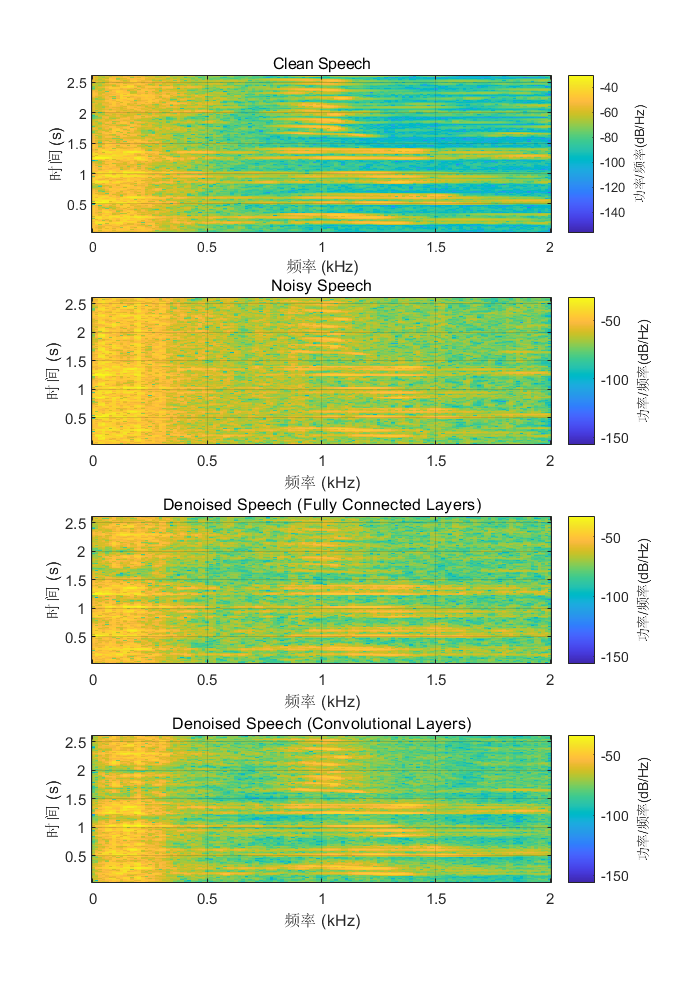


h = figure;

subplot(4,1,1)
spectrogram(cleanAudio,win,overlap,ffTLength,fs);
title("Clean Speech")
grid on

subplot(4,1,2)
spectrogram(noisyAudio,win,overlap,ffTLength,fs);
title("Noisy Speech")
grid on

subplot(4,1,3)
spectrogram(denoisedAudioFullyConnected,win,overlap,ffTLength,fs);
title("Denoised Speech (Fully Connected Layers)")
grid on

subplot(4,1,4)
spectrogram(denoisedAudioFullyConvolutional,win,overlap,ffTLength,fs);
title("Denoised Speech (Convolutional Layers)")
grid on

p = get(h,'Position');
set(h,'Position',[p(1) 65 p(3) 800]);


% sound(noisyAudio,fs)

% sound(denoisedAudioFullyConnected,fs)
audiowrite(fullfile(input,'connected.wav'),denoisedAudioFullyConnected,fs);

% sound(denoisedAudioFullyConvolutional)
audiowrite(fullfile(input,'convolutional.wav'),denoisedAudioFullyConvolutional,fs);

Listen to clean speech.

sound(cleanAudio,fs)

[cleanAudio,noisyAudio,denoisedAudioFullyConnected,denoisedAudioFullyConvolutional] = testDenoisingNets(ads,denoiseNetFullyConnected,denoiseNetFullyConvolutional,noisyMean,noisyStd,cleanMean,cleanStd);